tic
u=[0:1:10]; %vary u from 0 to 1000 also
figure1=figure('Position',[100,100,7000,10000])

figure1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [100 100 7000 10000]
       Units: 'pixels'

  Show all properties


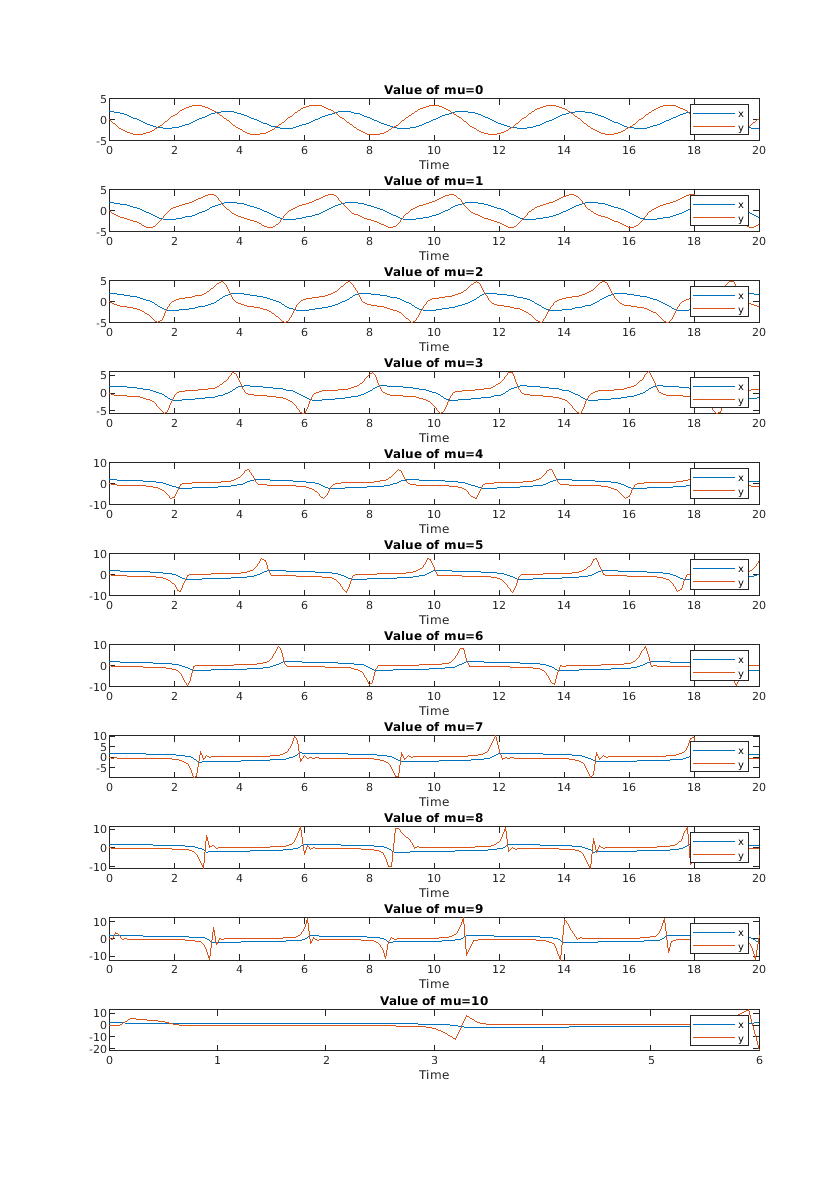

for j=1:length(u)
    
h = 0.1;
t=[0:h:20]';
N = length(t);


x = zeros(1,N);
x(1) = 2;
y = zeros(1,N);
y(1) = 0;

h = 0.1; %Step Size



    fx = @(x,y) y;
    fy = @(x,y) u(j)*(1-x*x)*y - 3*x;
    
    % Generating second initial value using 3RK
    k1 = [fx(x(1), y(1));
         fy(x(1), y(1))];
    k2 = [fx(x(1) + (h/2)*k1(1), y(1) + (h/2)*k1(2));
         fy(x(1) + (h/2)*k1(1), y(1) + (h/2)*k1(2))];
    k3 = [fx(x(1) - h*k1(1) + 2*h*k2(1), y(1) - h*k1(2) + 2*h*k2(2));
         fy(x(1) - h*k1(1) + 2*h*k2(1), y(1) - h*k1(2) + 2*h*k2(2))];
    x(2) = x(1) + (h/6)*(k1(1) + 4*k2(1) + k3(1));
    y(2) = y(1) + (h/6)*(k1(2) + 4*k2(2) + k3(2));
    
    % Initiating Adam-Moulton
    for i = 2:N-1
        for k=1:100
            x(i+1) = x(i) + (h/12)*(5*fx(x(i+1),y(i+1)) + 8*fx(x(i),y(i))- fx(x(i-1),y(i-1)));
            y(i+1) = y(i) + (h/12)*(5*fy(x(i+1),y(i+1)) + 8*fy(x(i),y(i))- fy(x(i-1),y(i-1)));
        end
    end
subplot(length(u),1,j);
plot(t,x)
hold on
plot(t,y)
title("Value of mu="+u(j))
xlabel('Time')
legend('x','y')
hold off
end

timetaken_stepsize_vary=toc

timetaken_stepsize_vary = 1.7032